# Surface reflectance properties

#sec-lightfield-properties

Show the basis functions for surface reflectances.  Then calculate the product of some daylights and surfaces to illustrate the variation in the incident light field with changes in ambient illumination.

Use the Mike Vrhel data set as the example, though perhaps the USGS data set too for materials?

Any chance we can find some standard functions for BRDFs and specular reflection that include both angle and wavelength?

imgdir = '~/Documents/FISE-git/chapters/images/lightfields';

## Typical reflectance functions

These are samples of clothing 

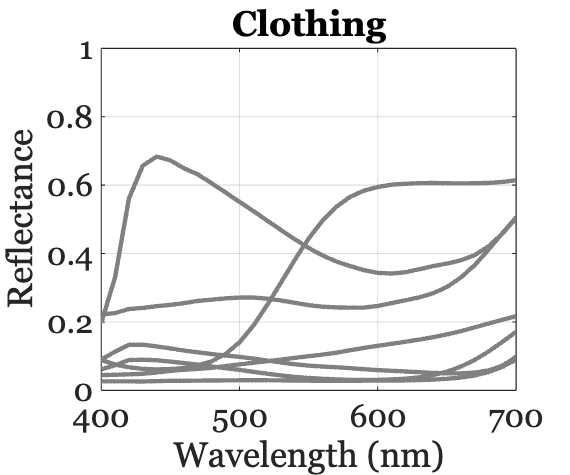

wave = 400:1:700;
[clothes,~,comment] = ieReadSpectra('Clothes_Vhrel',wave);
plotReflectance(wave,clothes(:,1:6:end),...
    'Color',[0.5 0.5 0.5], ...
    'title','Clothing');
set(gca,'ylim',[0 1]);
% {
exportgraphics(gca,fullfile(imgdir,'01-reflectance-clothes.png'),...
    'Resolution',150);

%}

## Sample measurements

Daylights from the [Granada color image](https://colorimaginglab.ugr.es/pages/data#__doku_granada_skylight_spectral_database) lab database

Peyvandi, Shahram, Javier Hernández-Andrés, F. J. Olmo, Juan Luis Nieves, and Javier Romero. 2016. “Colorimetric Analysis of Outdoor Illumination across Varieties of Atmospheric Conditions.” *Journal of the Optical Society of America. A, Optics, Image Science, and Vision* 33 (6): 1049–59.

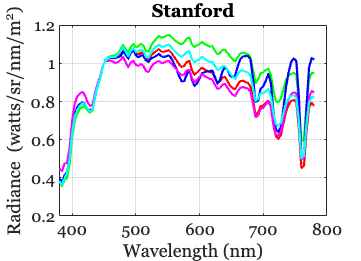

wave = 380:780;

% Should we have a normalized wave option for this method?
stanford = ieReadSpectra('daylightStanford',wave);
granada  = ieReadSpectra('daylightGranada',wave);
for ii=1:size(stanford,2)
    stanford(:,ii) = stanford(:,ii)/stanford(wave==450,ii);
end
for ii=1:size(stanford,2)
    granada(:,ii) = granada(:,ii)/granada(wave==450,ii);
end
% idx = randi(size(stanford,2),[1,5]);
idx = [54   527   208   133   222];
ieFigure;
plotRadiance(wave,stanford(:,idx));
set(gca,'userdata',idx);
title('Stanford')

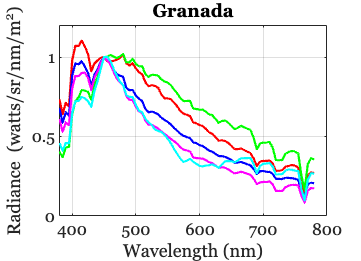

% idx = get(hdl1,'userdata')

% idx = randi(size(granada,2),[1,5]);
idx = [230   297    67   996   442];
ieFigure;
plotRadiance(wave,granada(:,idx));
set(gca,'userdata',idx);
title('Granada')

% idx = get(hdl2,'userdata')

%{ 
hdl = ieFigure([],'wide');
tiledlayout(1,2);
nexttile;
plotRadiance(wave,stanford(:,idx),'hdl',hdl);
ylabel('Normalized radiance (re:450)')
title('Stanford')
nexttile;
plotRadiance(wave,granada(:,idx),'hdl',hdl);
title('Granada')
ylabel('Normalized radiance (re:450)')
set(gcf,'Position',[0.0133    0.5188    0.5223    0.3882]);
A = findobj(gcf,'Type','axes');
set(A(1),'ylim',[0,1.3],'FontSize',16);
set(A(2),'ylim',[0,1.3],'FontSize',16);
exportgraphics(gcf,fullfile(imgdir,'01-solar-samples.png'),...
    'Resolution',150);
%}

## The Judd Macadam Wyszecki Daylight model

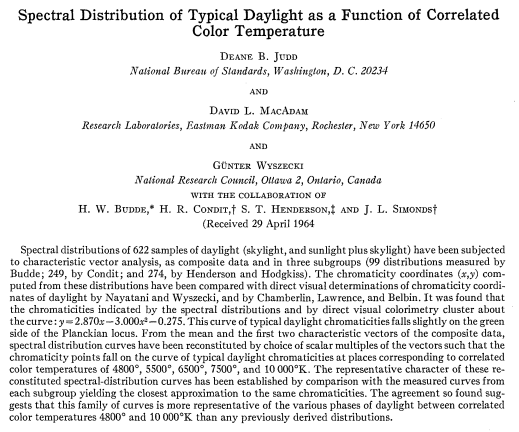%

This group and several others measured the spectral distributions of irradiance at the Earth's surface.  The found a two-dimensional linear model that described a large percentage of the variance of their (normalized) data (mean plus two basis vectors).  These have been confirmed by other authors, and here is the models that has been adopted as a CIE standard.

This plot shows the three functions along with a circle at several of the Fraunhofer lines.  You can see how the small discontinuities in the mean at most of these lines.

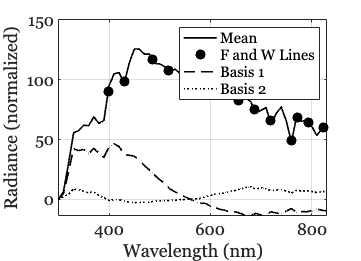

[dayBasis,wave] = ieReadSpectra('cieDaylightBasis');

ieFigure;
sym = {'k-','k--','k:'};
for ii=1:3
    plot(wave,dayBasis(:,ii),sym{ii},'LineWidth',1.5); hold on;
    if ii==1
        tmp = interp1(wave,dayBasis(:,ii),[earthLines, solarLines]);
        plot([earthLines, solarLines],tmp,'ko',...
            'MarkerSize',8,'MarkerFaceColor','k');
    end
end
grid on;
set(gca,'xlim',[300 830]);
legend({'Mean','F and W Lines','Basis 1','Basis 2'});
xlabel('Wavelength (nm)'); ylabel('Radiance (normalized)');


%{
exportgraphics(gca,fullfile(imgdir,'01-solar-basis.png'),...
    'Resolution',150);
%}


## Stanford sunlight

These are the average daylight SPD measurements, across an entire year, made by Jeff DiCarlo outside his office window at Stanford.  The solid curve shows the measurement, the '*' are Fraunhofer lines, and the dashed curve is the fit to the data from the CIE daylight basis functions.

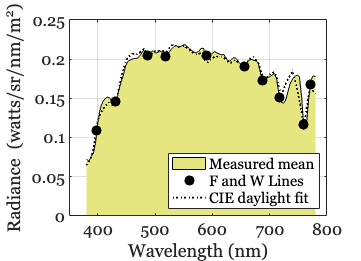

[spd,wave] = ieReadSpectra('daylightStanford');
spdM = mean(spd,2);

ieFigure;
% plot(wave,spdM,'k-','LineWidth',1.5); hold on;
hA = area(wave,spdM,'FaceColor',[0.9 0.9 0.5]); hold on;

% {
tmp = interp1(wave,spdM,[earthLines, solarLines]);
hB = plot([earthLines, solarLines],tmp,'ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','k');
%}

dayBasis = ieReadSpectra('cieDaylightBasis',wave);
wgts = pinv(dayBasis)*spdM;
pred = dayBasis*wgts;
hC = plot(wave,pred,'k:','LineWidth',1.5);

grid on;
set(gca,'xlim',[350 800]);
xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2)');
legend([hA,hB,hC],{'Measured mean','F and W Lines','CIE daylight fit'},'location','southeast');

%{
exportgraphics(gca,fullfile(imgdir,'01-solar-stanford.png'),...
    'Resolution',150);

%}
